# ECE 343 / MCOM 2025 - OFDM Simulation Project

% Author: Kumar Rishav Lakshay Kumar 
% Instructor: Shamik Sarkar
% Based on Project Description Dated: April 20, 2025
% Version: 2 (Manual QAM Mapping/Demapping)

clear; clc; close all;


## User and Default Parameters

audioFilename = 'recorded.wav';     % Name of audio file
recordNewAudio = false;             % true = record new, false = load existing 
audioDuration = 10;                 % Record length in seconds
M = 64;                             % 64-QAM
bitsPerSymbol = log2(M);            % Number of symbols
default_Emin = 10e-9;               % Default Emin Value
numSubcarriers = 256;               % Number of Sub Carrier
cpLength = 64;                      % Number of Cyclic Prefix
default_numPaths = 4;               % Number of path Delay in Multipath model
default_pathDelays_us = [0,5,10,15];% Path delay in vector form
default_Fs = 1e6;                   % default Sampling Frequency
default_Ts = 1/default_Fs;          % default Sampling Time
default_noisePSD = 1e-18;           % default Noise PSD(Power Spectral Density)
rng(42);                            % For reproducibility Seed of Noise


## Option and Pamameter Change code

% Option Emin IF condition Else Default values
Emin_user = input(sprintf('Enter Emin [default: %.2e]: ', default_Emin));
if isempty(Emin_user)
    Emin_user = default_Emin;
    fprintf('Using default Emin = %.2e\n', Emin_user);
end

Using default Emin = 1.00e-08



% Option Number of Multipath IF condition Else Default values
numPaths_user = input('Enter # multipath channels [default: 4]: ');
if isempty(numPaths_user)
    numPaths = default_numPaths;
else 
    numPaths = numPaths_user;
end

% Option Multipath Path delays IF condition Else Default values
pathDelays_us_user = input(sprintf('Enter path delays (µs) length %d [default: 0 5 10 15]: ', numPaths), 's');
if isempty(pathDelays_us_user)
    pathDelays_us = default_pathDelays_us;
else
    pathDelays_us = str2num(pathDelays_us_user);
end

% Option Sampling Frequency IF condition Else Default values
Fs_user = input('Enter Fs in Hz [default: 1e6]: ');
if isempty(Fs_user)
    Fs = default_Fs;
    Ts = 1/default_Fs; 
else 
    Fs = Fs_user;
    Ts = 1/Fs_user; 
end

% Option Noise Power IF condition Else Default values
noisePSD_user = input('Enter noise PSD W/Hz [default: 1e-18]: ');
if isempty(noisePSD_user)
    noisePSD = default_noisePSD; 
else 
    noisePSD = noisePSD_user;
end




## Audio Input Processing 

fprintf('STEP 1: Audio Input and preprocesing \n');     %Intiallization of audio input and preprocessing of input into bits

STEP 1: Audio Input and preprocesing 



if recordNewAudio                             % If condition to check whether a new audio recording is required
    recorder = audiorecorder;                 % Createing  an audiorecorder object for recording if is selected
    recordblocking(recorder,audioDuration);   % Recording audio for 'audioDuration = 10 Second' seconds, blocking execution until done
    audioSignal = getaudiodata(recorder);     % Extracting the recorded audio signal as an array
    audioFs = recorder.SampleRate;            % Getting the sampling frequency used by the recorder
    bits = recorder.BitsPerSample;            % Getting the number of bits per audio sample
    audiowrite(audioFilename,audioSignal,audioFs,'BitsPerSample',bits);  % Saveing the audio to .wav format to use it later 
else
    [audioSignal,audioFs] = audioread(audioFilename);  % Reading the existing .wav audio file
    info = audioinfo(audioFilename);          % Get metadata about the audio file # refereced for matlab audio processing 
    bits = info.BitsPerSample;                % Extracting the bit depth from metadata # refereced for matlab audio processing 
end
sound(audioSignal);                           % Playing the orignal audio signal

% If stereo (multiple channels), convert to mono by keeping first channel  # refereced for matlab audio processing 
if size(audioSignal,2)>1
    audioSignal=audioSignal(:,1);
end 

% Normalize audio to the range [-1, 1] for better quantization
audioSignal = double(audioSignal);                  % Converting audio to double precision for processing
audioSignal = audioSignal / max(abs(audioSignal));  % Normalizeing the signal to ensure peak value is 1 or -1

% Convert normalized floating-point audio to appropriate integer type based on bit depth
switch bits
  case 8
    % For 8-bit audio, map [-1,1] to [0,255] and store as unsigned integers
    audioInt = uint8((audioSignal + 1) * 127.5); 
    typeStr = 'uint8';                  % Save the type string for reference
  case 16
    % For 16-bit audio, map [-1,1] to [-32768,32767] and store as signed integers
    audioInt = int16(audioSignal * 32767); 
    typeStr = 'int16';
  otherwise
    % For other bit depths, convert using general formula and store as signed integers
    audioInt = int32(audioSignal * (2^(bits-1)-1));
    typeStr = 'int32';
end

% Convert integer audio stream to raw bytes, then to binary bitstream
audioBytes = typecast(audioInt(:), 'uint8');           % Flattening the audio array and cast it to raw 8-bit byte format
binaryStrings = dec2bin(audioBytes, 8);                % Converting each byte to its 8-bit binary representation (as strings)
audioBits_Tx = reshape(binaryStrings.' - '0', [], 1);  % Convert binary strings to a column vector of bits (0s and 1s)
original_num_bits = numel(audioBits_Tx);               % Store the total number of bits for later use



## 64-QAM Modulation

fprintf('STEP 2: QAM Modulation\n');                         % Intiallizing the QAM modulation 

STEP 2: QAM Modulation


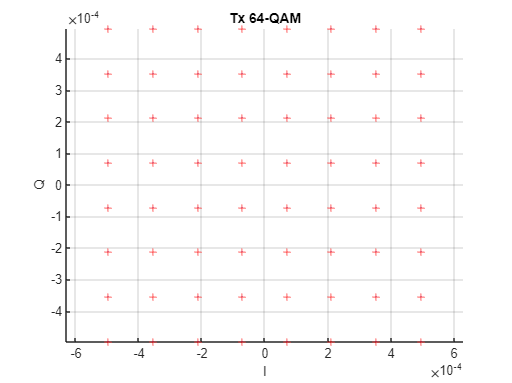


% Check if total number of bits is divisible by bits per QAM symbol
remainder = mod(original_num_bits, bitsPerSymbol);          % Find leftover bits
if remainder ~= 0
    % If leftover bits exist, pad with zeros to complete the last symbol
    audioBits_Tx = [audioBits_Tx; zeros(bitsPerSymbol - remainder, 1)];
end

% Reshapeing bitstream into rows of 'bitsPerSymbol' bits, 
% one row per symbol for QAM Modulation 
reshaped = reshape(audioBits_Tx, bitsPerSymbol, []).';      % Each row is one symbol in binary

% Convert each binary row (most significant bit on the left) to its decimal symbol index
symIdx = bi2de(reshaped, 'left-msb');                       % Getting QAM symbol indices (0 to M-1)

audioSymbols_Tx = symIdx;                                   % Saveing the transmitted symbols for later Symbol Error Rate (SER) comparison

% Generate reference QAM constellation with unit average power
ref_const = qammod(0:M-1, M, 'UnitAveragePower', true);     % Standard QAM constellation points for plotting

% Find minimum symbol energy from reference constellation
Emin_ref = min(abs(ref_const).^2);                          % Computeing minimum energy among all constellation points

% Compute scaling factor to match user-defined minimum symbol energy
scaleFact = sqrt(Emin_user / Emin_ref);                     % Calculate scaling to enforce desired minimum energy

% Perform actual QAM modulation with same indexing and scaling
qamSyms = qammod(symIdx, M, 'UnitAveragePower', true) * scaleFact;  % Modulate the symbols and apply scaling

% Plotting the QAM constellation
figure;
scatter(real(qamSyms), imag(qamSyms), 15, 'b.'); hold on; grid on; axis equal;  % Scatter plot of transmitted QAM symbols
plot(real(ref_const * scaleFact), imag(ref_const * scaleFact), 'r+');           % Overlay scaled reference constellation
title('Tx 64-QAM'); xlabel('I'); ylabel('Q');                                   % Label the plot axes and title

## STEP 3: OFDM MODULATION

fprintf('STEP 3: OFDM Modulation\n');     % Display header indicating the start of the OFDM transmission step

STEP 3: OFDM Modulation



numDataSymbols = numel(qamSyms);            % Count the total number of QAM symbols to be transmitted

numOFDMSym = ceil(numDataSymbols / numSubcarriers);  
                                            % Computeing how many full OFDM symbols are needed
                                            % Each OFDM symbol carries 'numSubcarriers' QAM symbols
                                            % Use ceil to round up to the next whole number 

padSyms = numOFDMSym * numSubcarriers - numDataSymbols;  
                                            % Calculateing how many zero-padding symbols for OFDM block 

txSymsPad = [qamSyms; zeros(padSyms, 1)];  
                                            % Appending zeros to the QAM symbol stream so it divides evenly across OFDM blocks

ofdmMat = reshape(txSymsPad, numSubcarriers, []);  
                                            % Reshapeing the padded symbol stream into a matrix
                                            % Each column is one OFDM symbol (i.e., 'numSubcarriers' QAM symbols per column)

ifftData = ifft(ofdmMat);  
                                            % Performing Inverse Fast Fourier Transform (IFFT) across each OFDM symbol
                                            % Converts frequency-domain data (QAM symbols) to time-domain samples

ofdmWithCP = [ifftData(end-cpLength+1:end, :); ifftData];  
                                            % Adding cyclic prefix (CP) to each OFDM symbol
                                            % CP is taken as the last 'cpLength' samples of the IFFT output and prepended to the start

txSignal = ofdmWithCP(:);  
                                            % This is the tx Signal to be transmitted
    

## CHANNEL SIMULATION

fprintf('STEP 4: Channel Construction\n');               

STEP 4: Channel Construction


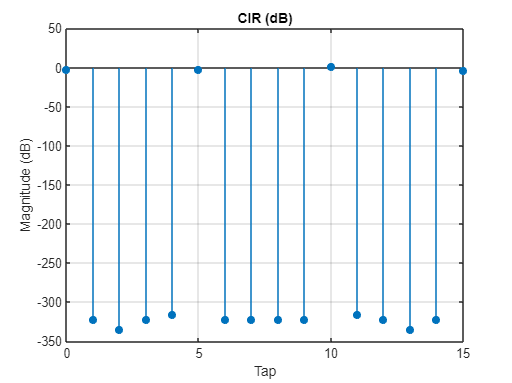

gains = (randn(1, numPaths) + 1i * randn(1, numPaths)) / sqrt(2);  % Converting delays from microseconds to fractional sample units for chanel 
del_samp = pathDelays_us * 1e-6 / Ts;                              
m = 0:15;                                                         % Create a sample index range for impulse response (16-tap filter) 
h = zeros(size(m));                                               % Initialize the impulse response vector

% Define a sinc function (handling divide-by-zero manually later)
sincfun = @(x) sin(pi * x) ./ (pi * x);  

% Construct the impulse response using delayed sinc pulses
for k = 1:numPaths
    d = del_samp(k);                  % Delay in samples for path k
    s = sincfun(m - d);               % Delayed sinc pulse
    s(m == d) = 1;                    % Handle sinc(0) = 1 explicitly
    h = h + gains(k) * s;             % Add weighted sinc to impulse response
end

% Plotting the Channel Impulse Response (in dB)
figure;
stem(m, 20 * log10(abs(h)), 'filled');
title('CIR (dB)');
xlabel('Tap');
ylabel('Magnitude (dB)');
grid on;

rxNoNoise = filter(h, 1, txSignal);     % Applying channel effect to transmitted OFDM signal using filtering
sigP = mean(abs(txSignal).^2);          % Calculate average signal power of transmitted signal
noiseP = noisePSD * Fs;                 % Compute total noise power using noise PSD and sampling frequency
SNRdB = 10 * log10(sigP / noiseP);      % Calculate SNR in dB

% Add complex Gaussian noise to the channel output
rxSignal = rxNoNoise + sqrt(noiseP / 2) * (randn(size(rxNoNoise)) + 1i * randn(size(rxNoNoise)));  



## OFDM DEMOD & EQUALIZATION

fprintf('STEP 5: OFDM Rx \n');

STEP 5: OFDM Rx 


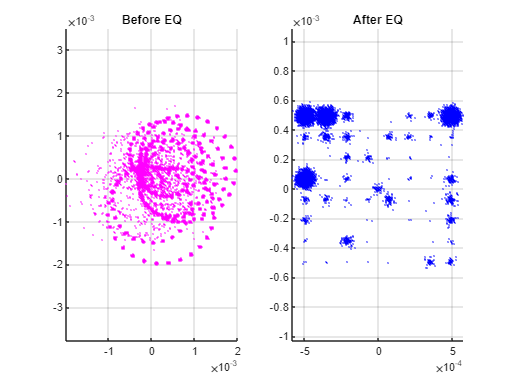



rxMat = reshape(rxSignal, numSubcarriers + cpLength, []); % Reshapeing the received signal into a matrix: (subcarriers + CP) x number of symbols
rxNoCP = rxMat(cpLength + 1:end, :);                      % Remove the cyclic prefix (CP) from each OFDM symbol
RXfft = fft(rxNoCP);                                      % Apply FFT to each column (symbol) to get frequency domain symbols
Hfft = fft([h, zeros(1, numSubcarriers - length(h))]);    % Compute the frequency response of the channel by zero-padding h to match subcarrier length and taking FFT
mmseW = conj(Hfft) ./ (abs(Hfft).^2 + 1 / (10^(SNRdB / 10)));% Compute the MMSE equalizer weights using channel response and SNR
eqSyms = RXfft .* mmseW.';                                % Apply the MMSE equalizer to the received frequency domain symbols

% Plot constellation diagrams before and after equalization
figure;
subplot(1,2,1);
scatter(real(RXfft(:)), imag(RXfft(:)), 15, 'm.'); % Before equalization
title('Before EQ'); axis equal; grid on;

subplot(1,2,2);
scatter(real(eqSyms(:)), imag(eqSyms(:)), 15, 'b.'); % After equalization
title('After EQ'); axis equal; grid on;

## QAM DEMODULATION

fprintf('STEP 6: QAM Demap \n'); % 64 QAM Demodulation 

STEP 6: QAM Demap 


rxSymsVec = eqSyms(:);                                    % Convert the equalized symbol matrix to a vector for demapping
rxSymsTrim = rxSymsVec(1:numDataSymbols) / scaleFact;     % Trim the vector to contain only the actual data symbols and scale them back (normalize)
rxIdx = qamdemod(rxSymsTrim, M, 'UnitAveragePower', true);% Perform QAM demodulation to get symbol indices (0 to M-1)
rxBits = de2bi(rxIdx, bitsPerSymbol, 'left-msb').';       % Convert the symbol indices to binary bits (each symbol to bitsPerSymbol bits)
rxBits = rxBits(:);                                       % Reshape the bit matrix to a column vector
rxBits = rxBits(1:original_num_bits);                     % Trim to the original number of transmitted bits

## RECONSTRUCT AUDIO

fprintf('STEP 7: Audio Out \n');  

STEP 7: Audio Out 



padEnd = mod(original_num_bits, 8);                           % Checking number of bits short the stream is from a full byte
if padEnd ~= 0, rxBits = [rxBits; zeros(8 - padEnd, 1)]; end  % Padding with zeros if needed to complete the last byte

bytesMat = reshape(rxBits, 8, []).';                          % Reshapeing bits into rows of 8 (each row is one byte)
charMat = char(bytesMat + '0');                               % Converting binary values to character '0' and '1'
rxBytes = uint8(bin2dec(charMat));                            % Converting binary string rows to uint8 decimal values
rxInt = typecast(rxBytes, typeStr);                           % Reinterpreting bytes as signed integers (e.g., int16, int8)

switch bits
    case 8
        rxSignalNorm = double(rxInt) / 127.5 - 1;             % Normalizeing 8-bit signed integers to [-1, 1]
    case 16
        rxSignalNorm = double(rxInt) / 32767;                 % Normalize 16-bit signed integers to [-1, 1]
    otherwise
        rxSignalNorm = double(rxInt) / (2^(bits - 1) - 1);    % General normalization for other bit depths
end

audiowrite('audio_reconstructed.wav', rxSignalNorm, audioFs, 'BitsPerSample', bits);  % Saveing normalized signal as WAV file

try
    fprintf('Playing reconstructed audio...\n');              
    sound(rxSignalNorm, audioFs);                              % Playing the reconstructed audio
catch
    warning('Could not play audio. Check your audio output device.');  % Errors Handling 
end

Playing reconstructed audio...


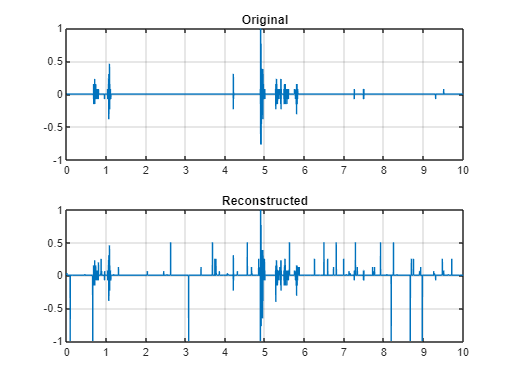


figure;  % Plotting orignal and reconstructed signals
t1 = (0:length(audioSignal) - 1) / audioFs;  % Time vector for original audio
t2 = (0:length(rxSignalNorm) - 1) / audioFs;  % Time vector for reconstructed audio
subplot(2,1,1), plot(t1, audioSignal); title('Original'); grid on;  % Plotting original signal
subplot(2,1,2), plot(t2, rxSignalNorm); title('Reconstructed'); grid on;  % Plotting reconstructed signal

## BER Calculation

fprintf('STEP 8: BER \n');  

STEP 8: BER 



minLength = min(length(audioBits_Tx), length(rxBits));  % Determine minimum length for alignment
audioBits_Tx = audioBits_Tx(1:minLength);               % Triming transmitted bits to match
rxBits = rxBits(1:minLength);                           % Triming received bits to match

bitErrors = sum(audioBits_Tx ~= rxBits);                % Counting the number of bit mismatches
BER = bitErrors / minLength;                            % Bit Error Rate
fprintf('Bit Errors: %d / %d\n', bitErrors, minLength); % Printing number of bit errors

Bit Errors: 98 / 640000


fprintf('BER = %.3e\n', BER);                           % Printing BER in scientific notation

BER = 1.531e-04


##  Symbol Error Rate (SER) Calculation


fprintf('STEP 9: Symbol Error Rate (SER)\n');

STEP 9: Symbol Error Rate (SER)



rxSymsTrim = rxSymsVec(1:numDataSymbols) / scaleFact;           % Trim and normalize received symbols
rxSymbols = qamdemod(rxSymsTrim, M, 'UnitAveragePower', true);  % QAM demodulate to get received symbol indices

minSymbols = min(length(audioSymbols_Tx), length(rxSymbols));   % Ensure both symbol vectors are the same length
txSym = audioSymbols_Tx(1:minSymbols);                          % Triming transmitted symbols
rxSym = rxSymbols(1:minSymbols);                                % Triming received symbols
symbolErrors = sum(txSym ~= rxSym);                             % Counting symbol mismatches
SER = symbolErrors / minSymbols;                                % Symbol Error Rate
fprintf('Symbol Errors: %d / %d\n', symbolErrors, minSymbols);  % Printing number of symbol errors

Symbol Errors: 98 / 106667


fprintf('SER = %.3e\n', SER);                                   % Printing SER in scientific notation

SER = 9.187e-04


## STEP 10: SNR Plot & Comparison

fprintf('STEP 10: SNR Check and calculation \n'); 

STEP 10: SNR Check and calculation 



receivedSignalPower = mean(abs(rxNoNoise).^2);      % Compute average power of received (clean) signal
measuredNoise = rxSignal - rxNoNoise;               % Estimate noise by subtracting clean signal from noisy received signal
measuredNoisePower = mean(abs(measuredNoise).^2);   % Compute average noise power
SNR_measured = 10 * log10(receivedSignalPower / measuredNoisePower);  % Compute measured SNR in dB

fprintf('Theoretical SNR = %.2f dB\n', SNRdB);          % Printing theoretical SNR

Theoretical SNR = 31.60 dB


fprintf('Measured SNR    = %.2f dB\n', SNR_measured);   % Printing measured SNR

Measured SNR    = 36.30 dB


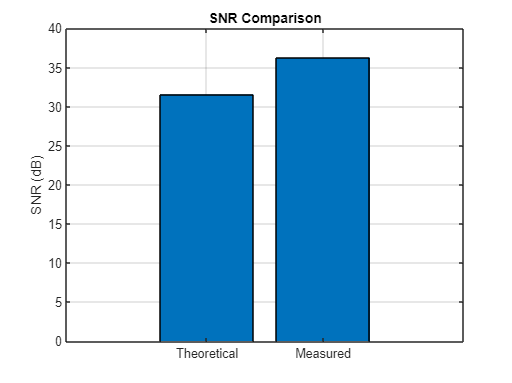


figure;  
bar([SNRdB, SNR_measured]);                             % Ploting bar graph comparing theoretical and measured SNR
set(gca, 'XTickLabel', {'Theoretical', 'Measured'});    % Set x-axis labels
ylabel('SNR (dB)');                                     % Label y-axis
title('SNR Comparison');  
grid on;  